# Lab 3: Position Control

**Learning Goals**

- Implement a PID controller.

- Identify rise time, settling time, overshoot, and peak time.

- Explain how changes to PID parameters affect the time-domain response.

DC motors are used in a wide variety of applications. They can be found in fans, treadmills, quadcopter drones, and electric vehicles, to name a few. In many of these applications, it is necessary to control the motor's speed or position. A feedback controller allows precise control of a motor's speed or position. In this lab, you will implement a PID controller to control the position of a virtual DC motor.

## Part I: DC motor position control implementation

In this part of the lab, you will implement the PID controller.

### PID Control

A PID controller uses a feedback loop with proportional, derivative, and integral terms to calculate the control signal. Together, the controller, plant, and feedback loop are often referred to as a *closed-loop system*.

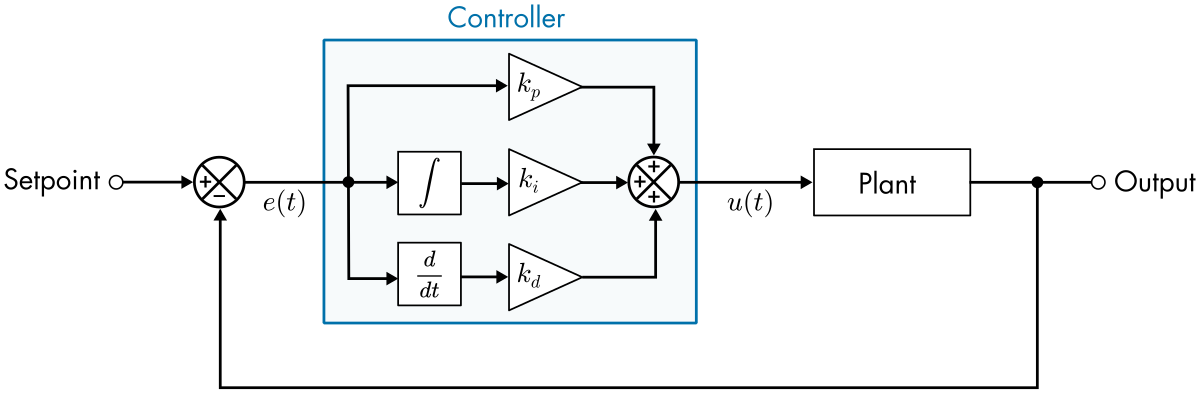

*Block diagram of a PID controller. The control signal *$u(t)$ *is the sum of the P, I, and D terms.*

Each of the PID terms is computed from the error, $e(t)$. The error is the difference between the setpoint and the current output value. 

- The **P**roportional term, $P =  k_p e$, is proportional to the error.

- The **I**ntegral term, $I = k_i \int_0^\tau e(\tau) d \tau$, is proportional to the integral of the error.

- The **D**erivative term, $D = k_d \frac{de}{dt}$, is proportional to the derivative of the error.

The control signal $u(t)$ is computed as the sum of all three terms:


$$u(t) = k_p e + k_i \int_0^\tau e(\tau) d \tau + k_d \frac{de}{dt}$$


The constants $k_p$, $k_i$, and $k_d$ determine the relative influence of each term. Appropriately selecting these constants is essential to any PID control application.

### Simulink Implementation

**Task 1.** To implement the PID controller in Simulink, open [`DCMotor.slx`](matlab: open_system("DCMotor.slx")) and add the controller to the model as shown in the diagram. For additional details, see the step-by-step instructions below.

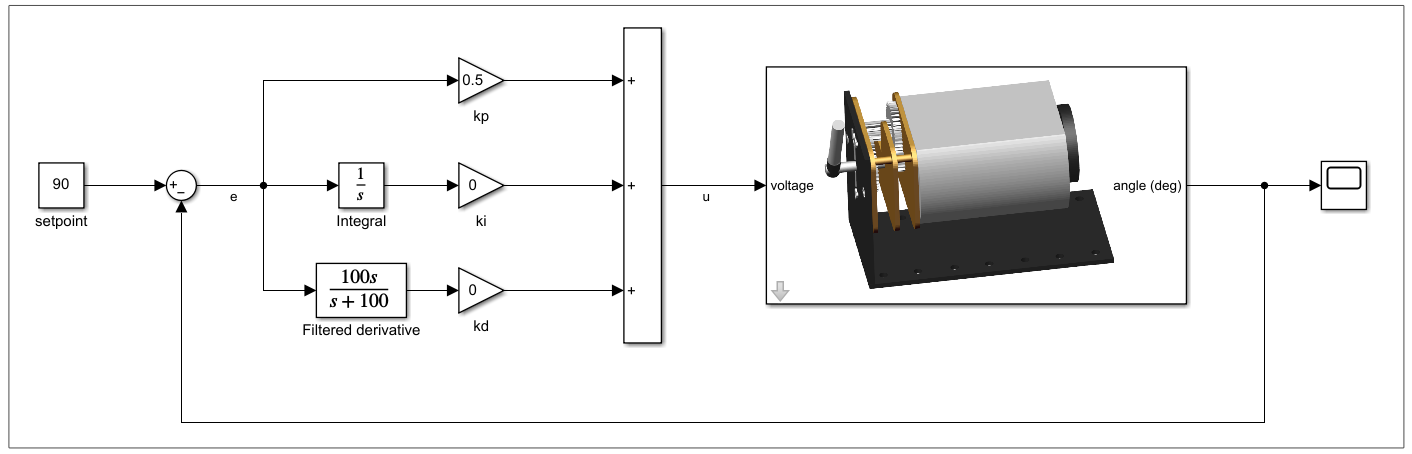

*PID controller implemented using basic Simulink blocks. The integral is computed using an Integrator block and the filtered derivative is computed using a Transfer Fcn block.*

**        Step-by-step instructions**

- Add a [Constant](https://www.mathworks.com/help/simulink/slref/constant.html) block with a value of 90 (this represents the setpoint of 90$^\circ$). 

- Add a [Sum](https://www.mathworks.com/help/simulink/slref/add.html) block. Double-click the Sum block to access the dialog. In the block dialog, set the **Icon shape** to **round** and the **List of signs** to `|+-`, so that the block appears as shown.

- Add an [Integrator](https://www.mathworks.com/help/simulink/slref/integrator.html) block and connect it to the output of the Sum block. Notice that the block is labeled $1/s$, the Laplace domain representation of an integral.

- Add a [Transfer Fcn](https://www.mathworks.com/help/simulink/slref/transferfcn.html) block. Double-click the Transfer Fcn block to access the dialog. In the dialog, set the numerator to `[100 0]` and the denominator to `[1 100]`. This block computes and filters the derivative.

- Add three [Gain](https://www.mathworks.com/help/simulink/slref/gain.html) blocks for $k_p$, $k_i$, and $k_d$. Set the gains to $k_p = 0.5 $ and $k_i = k_d = 0$.

- Add an [Add](https://www.mathworks.com/help/simulink/slref/add.html) block and stretch it vertically by clicking and dragging one of the corners of the Add block. Then, connect all three gains to the Add block. To create a third plus sign, drag the third signal to the block. This will cause an additional input to automatically be created.

- Add a [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) block to the plant output so that you can observe the angle.

**Task 2. **Test the controller.

- Double-click the motor image to show the plant parameters. 

- Set the virtual DC motor parameters to ***B***** = 0.028 **N$\cdot$m/(rad/s), **K = 0.05 **V/(rad/s),** L = 0.1 **H, **R = 0.25** Ohm, **Pendulum mass = 0.15 **Kg, **Pendulum length = 0.015 **m, and **Sensor noise gain = 0**. Also, turn voltage saturation off by unchecking the **Use voltage saturation** checkbox. 

- Set the simulation** Stop Time** to **5**.

- Run  the model. If correct, the output in the scope should appear as shown below. Notice how the arm oscillates back and forth around the setpoint before settling down in the Mechanics Explorer.

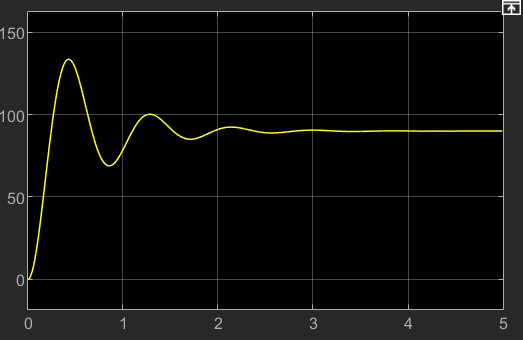

*Result of running the PID controlled DC motor model with *$k_p = 0.5 $, $k_i = k_d = 0$. *This plot characterizes the response of the closed-loop feedback system to a step input.*

## Part 2: Manual PID tuning

### Time response characteristics

In the previous example, the motor overshot the setpoint by more than 40$^\circ$ and took around 2 seconds to settle down to the target position of 90$^\circ$. This happened because the PID parameters are not optimal for the system. The PID parameters can be tuned to improve the controller response. With a manual tuning approach, the controller gains are adjusted to improve several standard time-response characteristics. The essential quantities are:

- *Rise time*: Time it takes for the response curve $y(t)$ to rise from 10% to 90% of the steady-state value $y_\infty$.

- *Settling time*: Time it takes for the difference between the response curve $y(t)$ and the steady-state value $y_\infty$ to the fall below 2%.

- *Overshoot*: How far the peak value $y_{peak}$ overshoots $y_\infty$. This is often expressed as a percentage: $100\% \cdot (y_{peak} - y_\infty)/y_\infty$.

- *Peak time*: Time at which the peak value occurs.

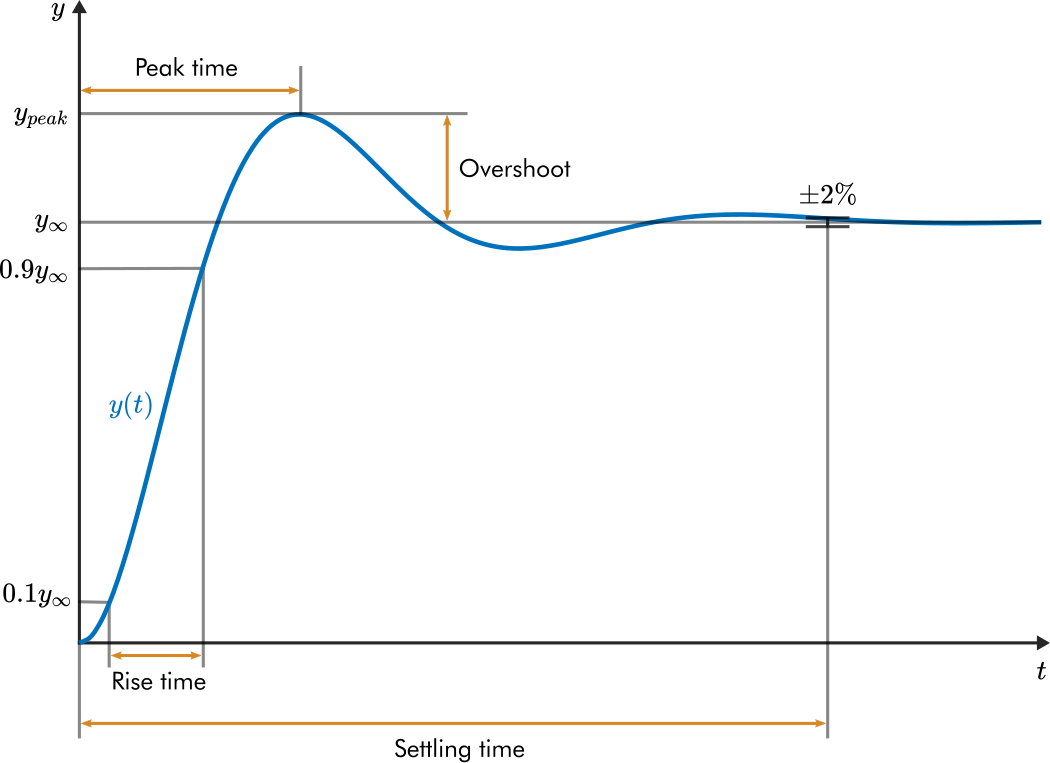

*Illustration of the Time response characteristics of a second-order response. *

**Task 3.** Estimate the step response characteristics of the controlled system you created in Simulink in the previous section. Continue to use the PID parameters $k_p = 0.5 $, $k_i = k_d = 0$ and the model parameters **B = 0.028 **Nm/(rad/s), **K = 0.05 **V/(rad/s),** L = 0.1 **H, **R = 0.25** Ohm, **Pendulum mass = 0.15 **Kg, **Pendulum length = 0.015 **m, and **Sensor noise gain = 0**. Also, turn voltage saturation off by unchecking the **Use voltage saturation** checkbox.

 **Pro-tip**: You can measure values in the scope using **Cursor Measurements**. From the Scope menu, select **Tools **> **Measurements **> **Cursor measurements. **Select and drag the vertical lines to change the measurement locations.

**a. **What is the peak value $y_{peak}$ (round to the nearest degree)?    

% Replace NaN with your answer
task3a = NaN

**b. **What is the settling value $y_\infty$ (round to the nearest degree)? 

task3b = NaN

**c.** What is the rise time in seconds (round to the nearest hundredth)?

task3c = NaN

**d. **What is the settling time in seconds (round to the nearest hundredth)?

task3d = NaN

**e. **What is the percent overshoot?    

task3e = NaN

**f. **What is the peak time in seconds (round to the nearest hundredth)?

task3f = NaN

### Qualitative tuning of the PID parameters

In this section, you will manually tune the PID parameters to improve the position control response. Independent manual adjustment of each PID parameter leads to predictable changes in the response of the closed-loop system. 


$$\begin{array}{lccc}
& \text{Rise time} & \text{Overshoot} & \text{Settling time}
\\
\text{Increase } k_p  & \downarrow& \uparrow & _\uparrow
\\
\text{Increase } k_i & _\downarrow& \uparrow & \uparrow
\\
\text{Increase } k_d &  _\downarrow & \downarrow & \downarrow
\end{array}$$


*Typical effects of independently adjusting the PID parameters on the response of the closed-loop system*

The parameters have additional effects besides those listed. For example, increasing the integral gain reduces the steady-state error. So, in systems that are prone to steady-state error, it is often useful to increase $k_i$.

**Task 4. **Run the tuning model.

- Open the completed DC motor control model, [`DCMotorControl.slx`](matlab: open_system("DCMotorControl.slx")).

- Double-click the motor image to show the parameters. Set the virtual DC motor parameters to ***B***** = 0.028 **Nm/(rad/s), **K = 0.05 **V/(rad/s),** L = 0.1 **H, **R = 0.25** Ohm, **Pendulum mass = 0.15 **Kg, **Pendulum length = 0.015 **m, and **Sensor noise gain = 0**. Also, turn voltage saturation off by unchecking the **Use voltage saturation** checkbox. 

- Run the model . Adjust the PID parameters three times using the dashboard controls. 

- For each parameter set, flip the setpoint back and forth between $90^\circ$ and $270^\circ$ to observe the alterations to the step response in both the graphs and the physical model displayed in the Mechanics Explorer. 

- You can stop the model using  .

**Task 5. **In this task, you will tune the PID parameters to obtain a good response. Because the controller's goal is to reach the setpoint as quickly as possible, a good response will have short rise and settling times and relatively little overshoot. Run  the model to get started. You can leave the model running for the duration of this task.

**a.** Start by setting all three PID parameters to zero. Then, gradually increase the proportional gain, $k_p$. Start with very small values of $k_p$ (e.g., $k_p = 0.05$). What happens to the time-domain characteristics of the step response as $k_p$ increases?

**Hint: **To observe the step response, start with a setpoint of $90^\circ$.  Then, switch the setpoint dial to $270^\circ$. You can flip the setpoint back to $90^\circ$ to observe another step response.

task5a = "<replace this text with your answer but keep the quotes>"

**b. **Set $k_p$ to 0.4 and then gradually increase the integral gain, $k_i$. Does this improve the performance of the controller? Why or why not?

task5b = "<replace this text with your answer but keep the quotes>"

**c. **Set $k_p$ to 1 and set $k_i$ to zero. Then, gradually increase the derivative gain, $k_d$. Does this improve the performance of the controller? Why or why not?

task5c = "<replace this text with your answer but keep the quotes>"

**d. **With $k_p = 1$ and $k_i = 0$, what is a good value (i.e., one that has a short rise time without overshoot) of the derivative term gain, $k_d$? 

task5d = NaN

**e. **Based on your observations, which controller appears to work best for this system?

- P controller (proportional control only)

- PI controller (proportional and integral terms)

- PD controller (proportional and derivative terms)

task5e = "-"

### 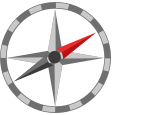**Further exploration**

Because the input motor voltage was unlimited in the last exercise, the motor was able to respond very quickly. In practice, the input voltage should be limited to the motor's nominal voltage (for example, 6V). There may also be noise in the position sensor readings.

- Turn on the voltage saturation (double-click the motor image and check **Use voltage saturation**) and try retuning the PID parameters. Does it appear that the best parameters have changed?

- Set the **Sensor noise** **gain** to 0.5 (double-click the motor image to access the dialog box). Does introducing sensor noise lead to noticeable issues?